T=readtable('D:\MATLAB\workspace_Model\data\data_predict_Matlab.xlsx');

% Model Fine Tree

y_fit_Tree = FineTree_5.predictFcn(T)

columns_tagets = {'energy'};
x_Tree = table2array(T(:, columns_tagets))

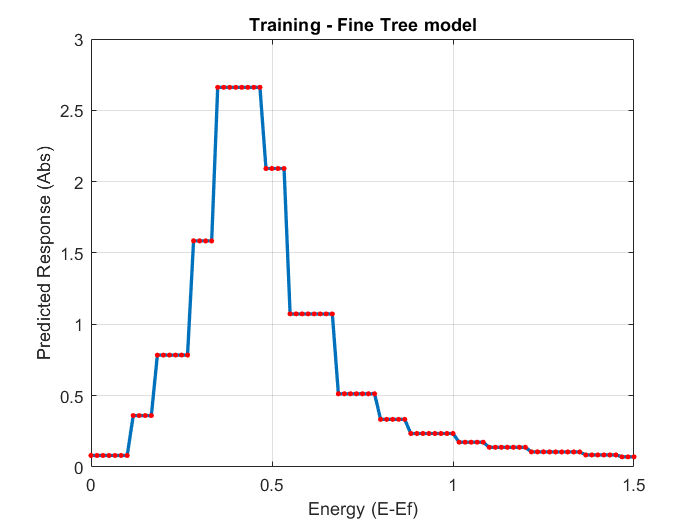

plot(x_Tree, y_fit_Tree, 'LineWidth', 2); 
hold on; 
scatter(x_Tree, y_fit_Tree, 10, 'Marker', 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', 'red'); % Hiển thị điểm giá trị với kích thước nhỏ hơn và không có viền
hold off;

xlabel('Energy (E-Ef)'); 
ylabel('Predicted Response (Abs)'); 
title('Training - Fine Tree model'); 

grid on; %  